**Initialization**

Set up the basic parameters for the airline overbooking model.

N = 200;        % Number of seats 
T = 300;        % Ticket price 
p = 0.95;       % Probability of a passenger showing up 
R_0 = T + 100;  % Base reimbursement amount
Delta_R = 100;  % Increase in reimbursement each round 
lambda = 0.01;  % Parameter for reimbursement acceptance probability 
shift = 2;      % Horizontal shift for the reimbursement acceptance probability 
max_overbooking_factor = 0.25; % Maximum overbooking percentage 

**Validate input parameters **

assert(N > 0, 'Error: Number of seats (N) must be positive');
assert(T > 0, 'Error: Ticket price (T) must be positive');
assert(p >= 0 && p <= 1, 'Error: Probability (p) must be in the range [0, 1]');
assert(Delta_R >= 0, 'Error: Reimbursement increment (Delta_R) must be non-negative');
assert(max_overbooking_factor >= 0, 'Error: Overbooking factor must be greater than or equal to zero');
assert(lambda >= 0 && lambda <= 10, 'Error: Lambda (lambda) must be in the range [0, 10]'); 

### **Define Probability of Accepting a Reimbursement **

Calculates the probability of accepting a reimbursement. 

Let $P_R(r)$ be the probability of the reimbursement $r$ being accepted by any passenger. One decent generalization of $P_R$ is of the form $\tanh(R)$ as follows: $P_R(R = x) = \frac{1 + \tanh(\lambda (x - \text{shift} \cdot T))}{2}$

P_R = @(R, lambda, shift, T) (1 + tanh(lambda * (R - shift * T))) / 2;

**Plot the reimbursement acceptance probability for visual analysis. **

acceptancePlot = run_with_ConsoleLog(@plotReimbursementAcceptance, P_R, R_0, lambda, shift, T); 

** Function Run:   plotReimbursementAcceptance 
** Execution Time: 1.4775 seconds 
** Success:        Function plotReimbursementAcceptance executed with 5 inputs. 


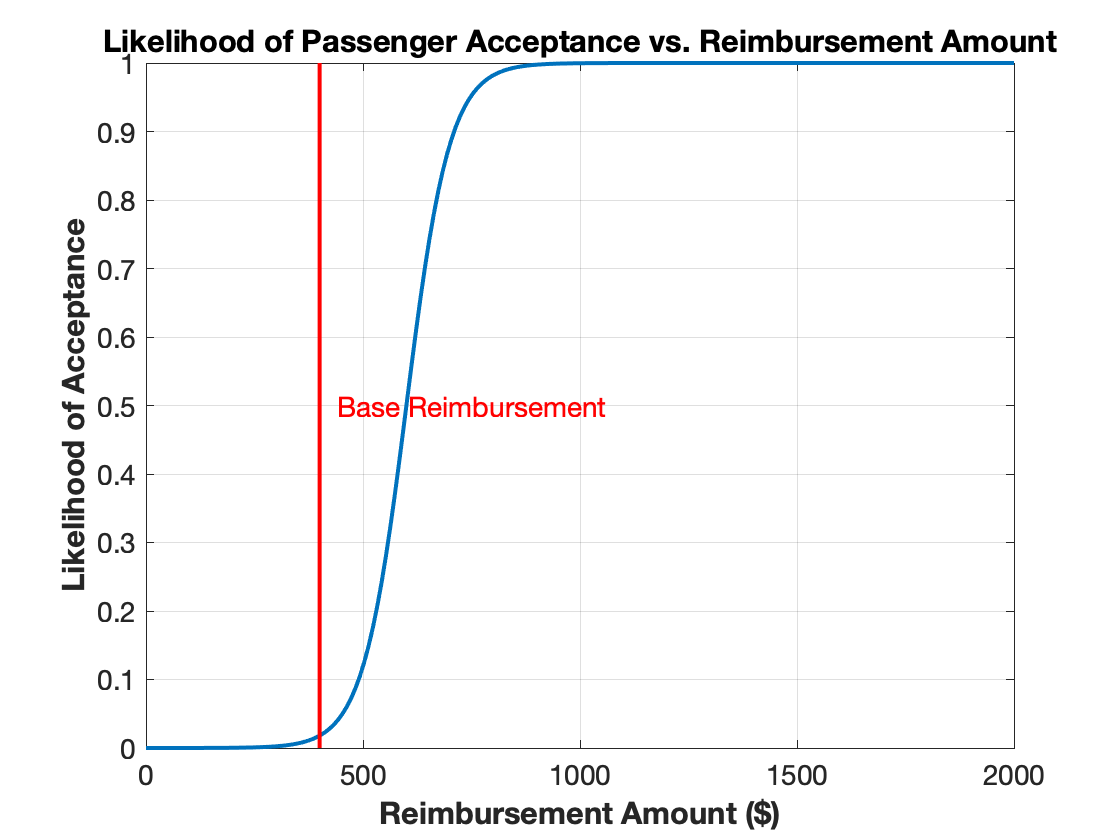

figure(acceptancePlot) 

Test variable the reimbursement acceptance probability with various lambda $\lambda$ values in $P_R(R = x) = \frac{1 + \tanh(\lambda (x - \text{shift} \cdot T))}{2}$ 

acceptancePlot_Varied_Parameters = run_with_ConsoleLog(@plotReimbursementAcceptance_Vary_Lambda, P_R, R_0, T, [0.005, 0.01, 0.02, 0.04], [2, 2, 2, 2]); 

** Function Run:   plotReimbursementAcceptance_Vary_Lambda 
** Execution Time: 0.8522 seconds 
** Success:        Function plotReimbursementAcceptance_Vary_Lambda executed with 5 inputs. 


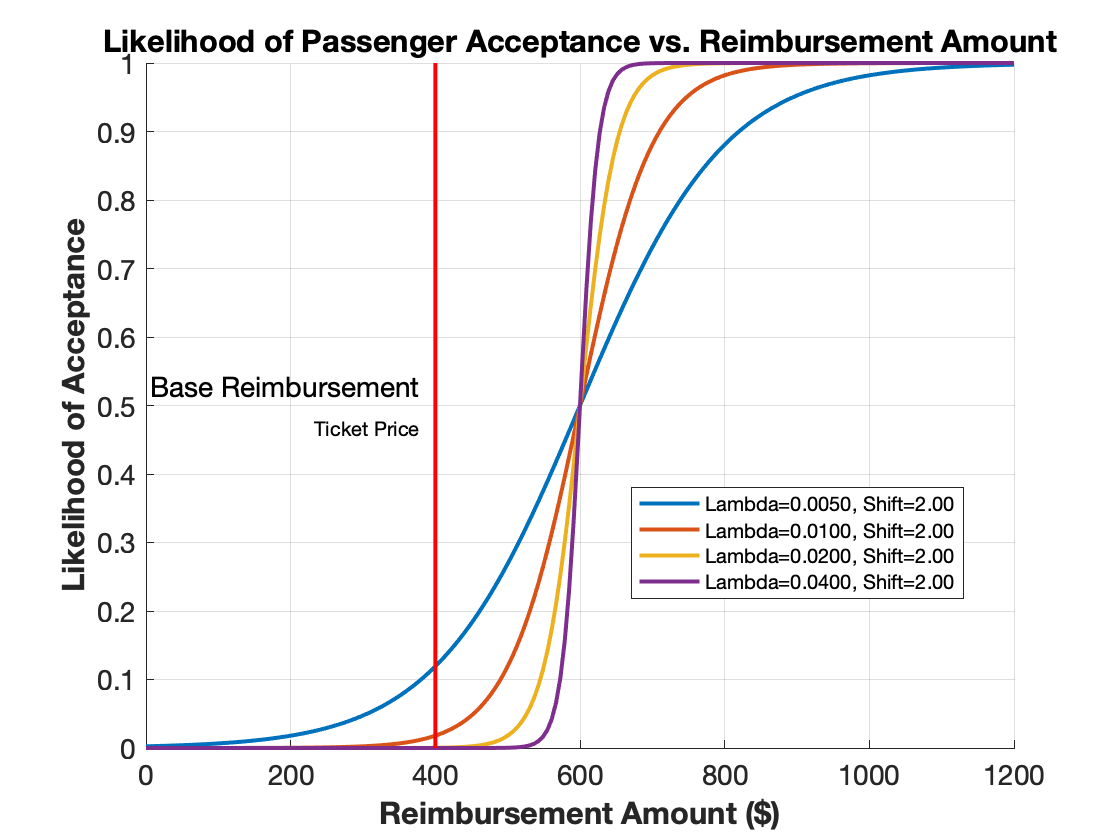

figure(acceptancePlot_Varied_Parameters) 

### **Analyze **$S$** Tickets Sold versus Expected Profit**

Define the range of tickets to sell 

S_min = N; % Minimum number of tickets to sell 
S_max = N + round(N * max_overbooking_factor); % Maximum number of tickets to sell 
S_range = S_min:S_max; % Range of tickets to sell 

### Expected Profit using Fixed Reimbursement for Overbooked Passengers (S is varied)

Plot expected profit using fixed reimbursement for varying numbers of tickets sold. 

Fixed_Reimbursement_Plot = run_with_ConsoleLog(@plotProfitFixedReimbursement, N, T, p, linspace(R_0, R_0 + Delta_R * 4, 5), S_range);

** Function Run:   plotProfitFixedReimbursement 
** Execution Time: 0.2434 seconds 
** Success:        Function plotProfitFixedReimbursement executed with 5 inputs. 


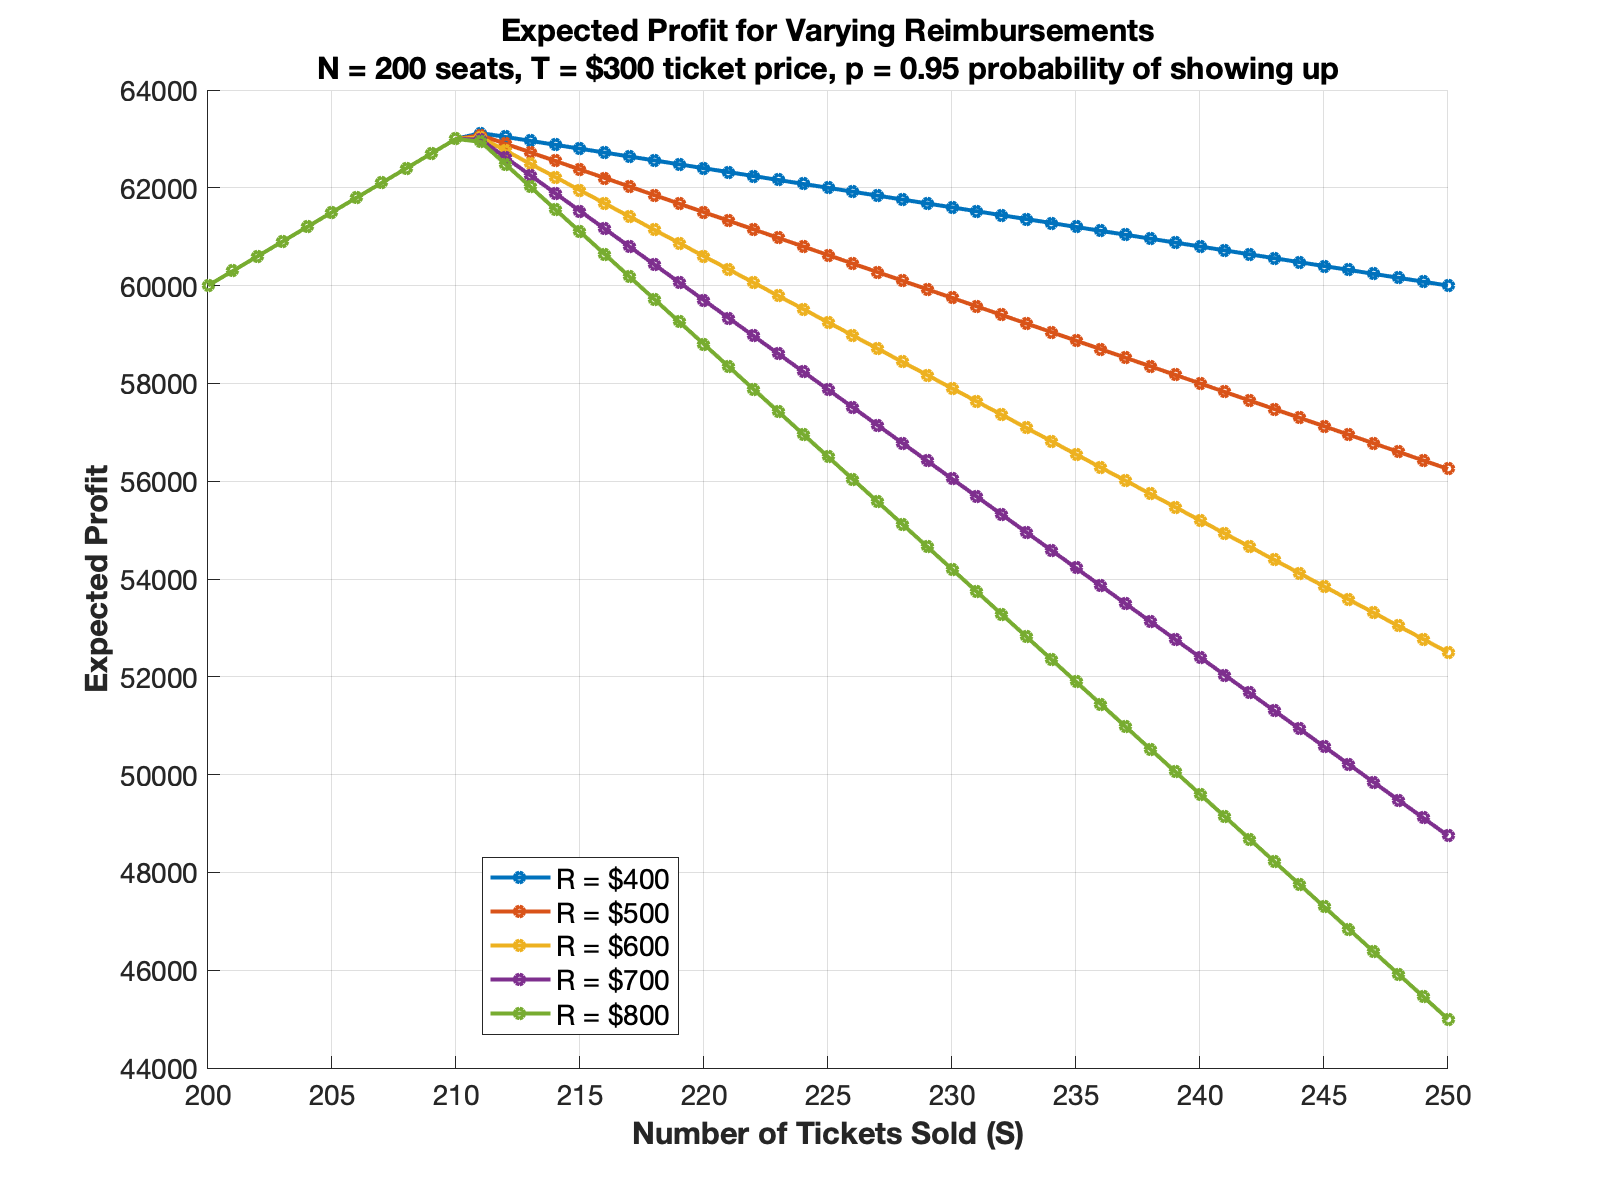

figure(Fixed_Reimbursement_Plot) 

### Expected Profit using Variable Reimbursements Based on Acceptance Probability (S is varied) 

% Plot expected profit using variable reimbursements based on acceptance probability 
[Expected_Profits_Plot_S, S_optimal] = run_with_ConsoleLog(@plotExpectedProfits_S, N, T, p, R_0, Delta_R, P_R, lambda, shift, max_overbooking_factor);

** Function Run:   plotExpectedProfits_S 
** Execution Time: 0.4674 seconds 
** Success:        Function plotExpectedProfits_S executed with 9 inputs. 


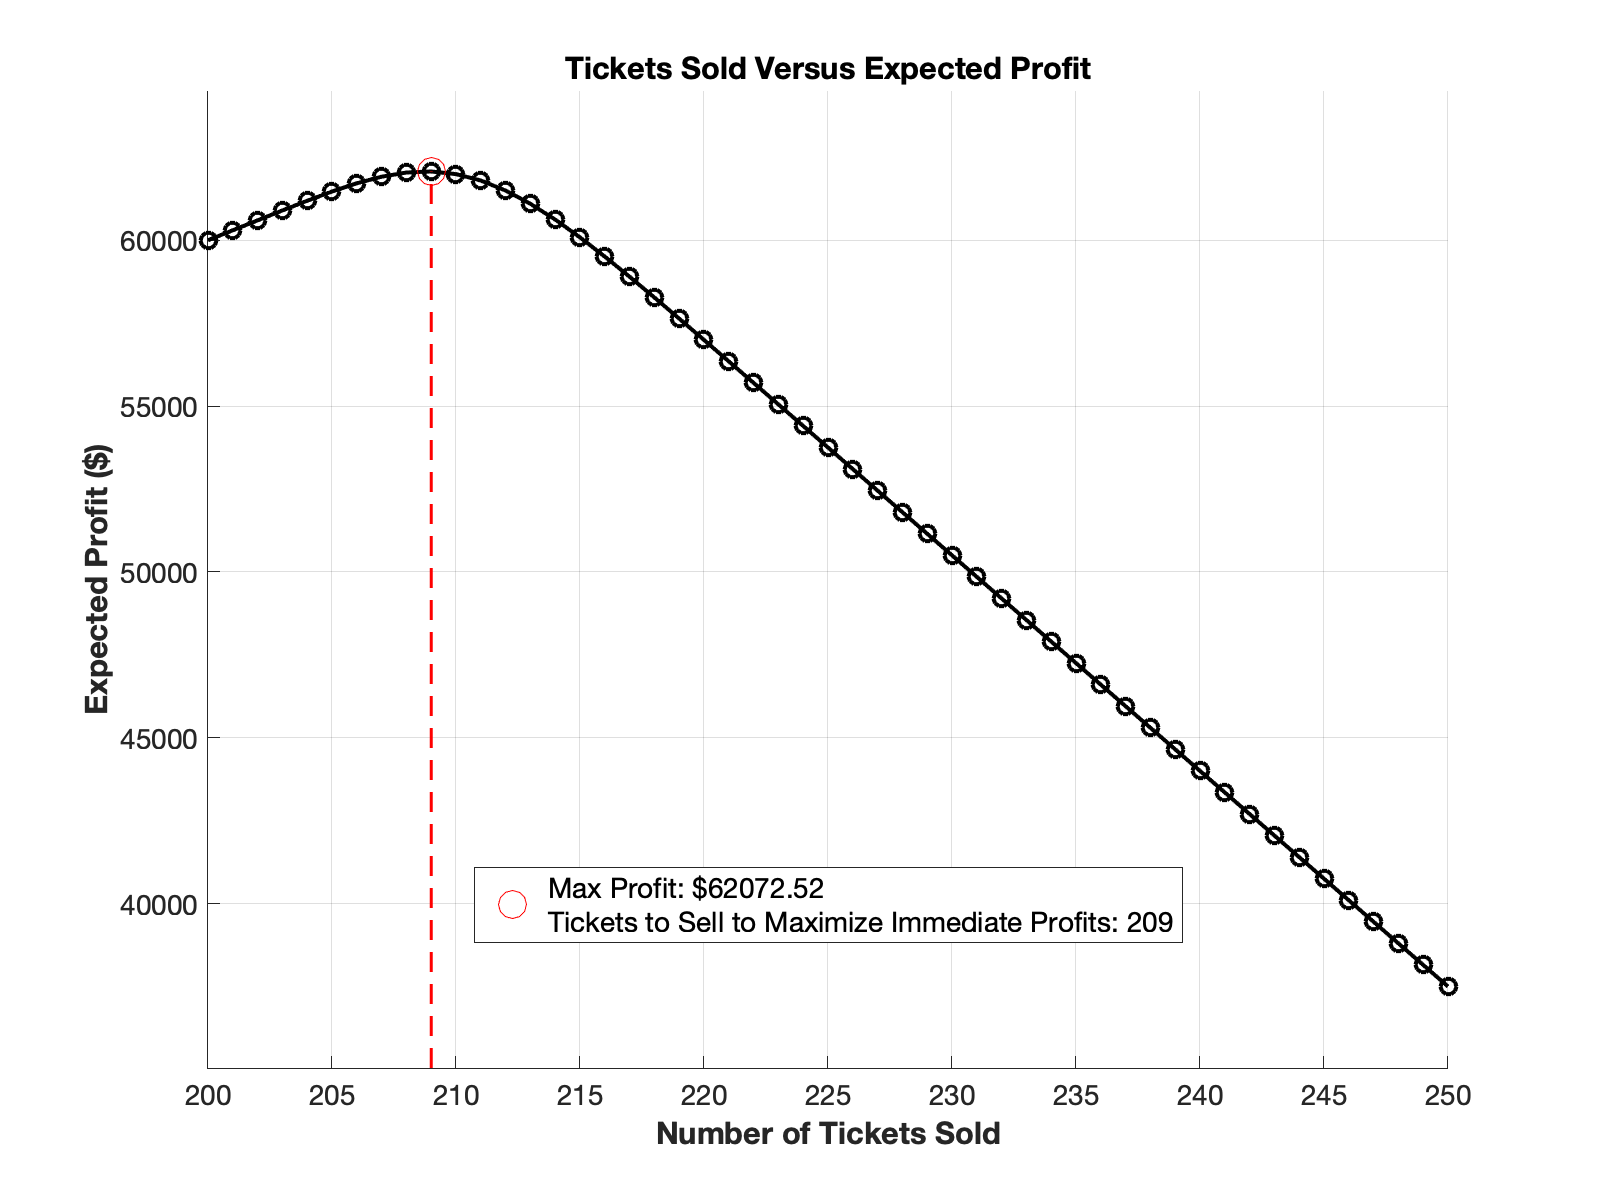

figure(Expected_Profits_Plot_S) 

### Expected Profit using Variable Reimbursements (p is Varied) 

Plot expected profit for varying passenger show-up probabilities. 

Expected_Profits_Plot_p = run_with_ConsoleLog(@plotExpectedProfit_p, N, S_optimal, T, R_0, Delta_R, P_R, lambda, shift);

** Function Run:   plotExpectedProfit_p 
** Execution Time: 0.2529 seconds 
** Success:        Function plotExpectedProfit_p executed with 8 inputs. 


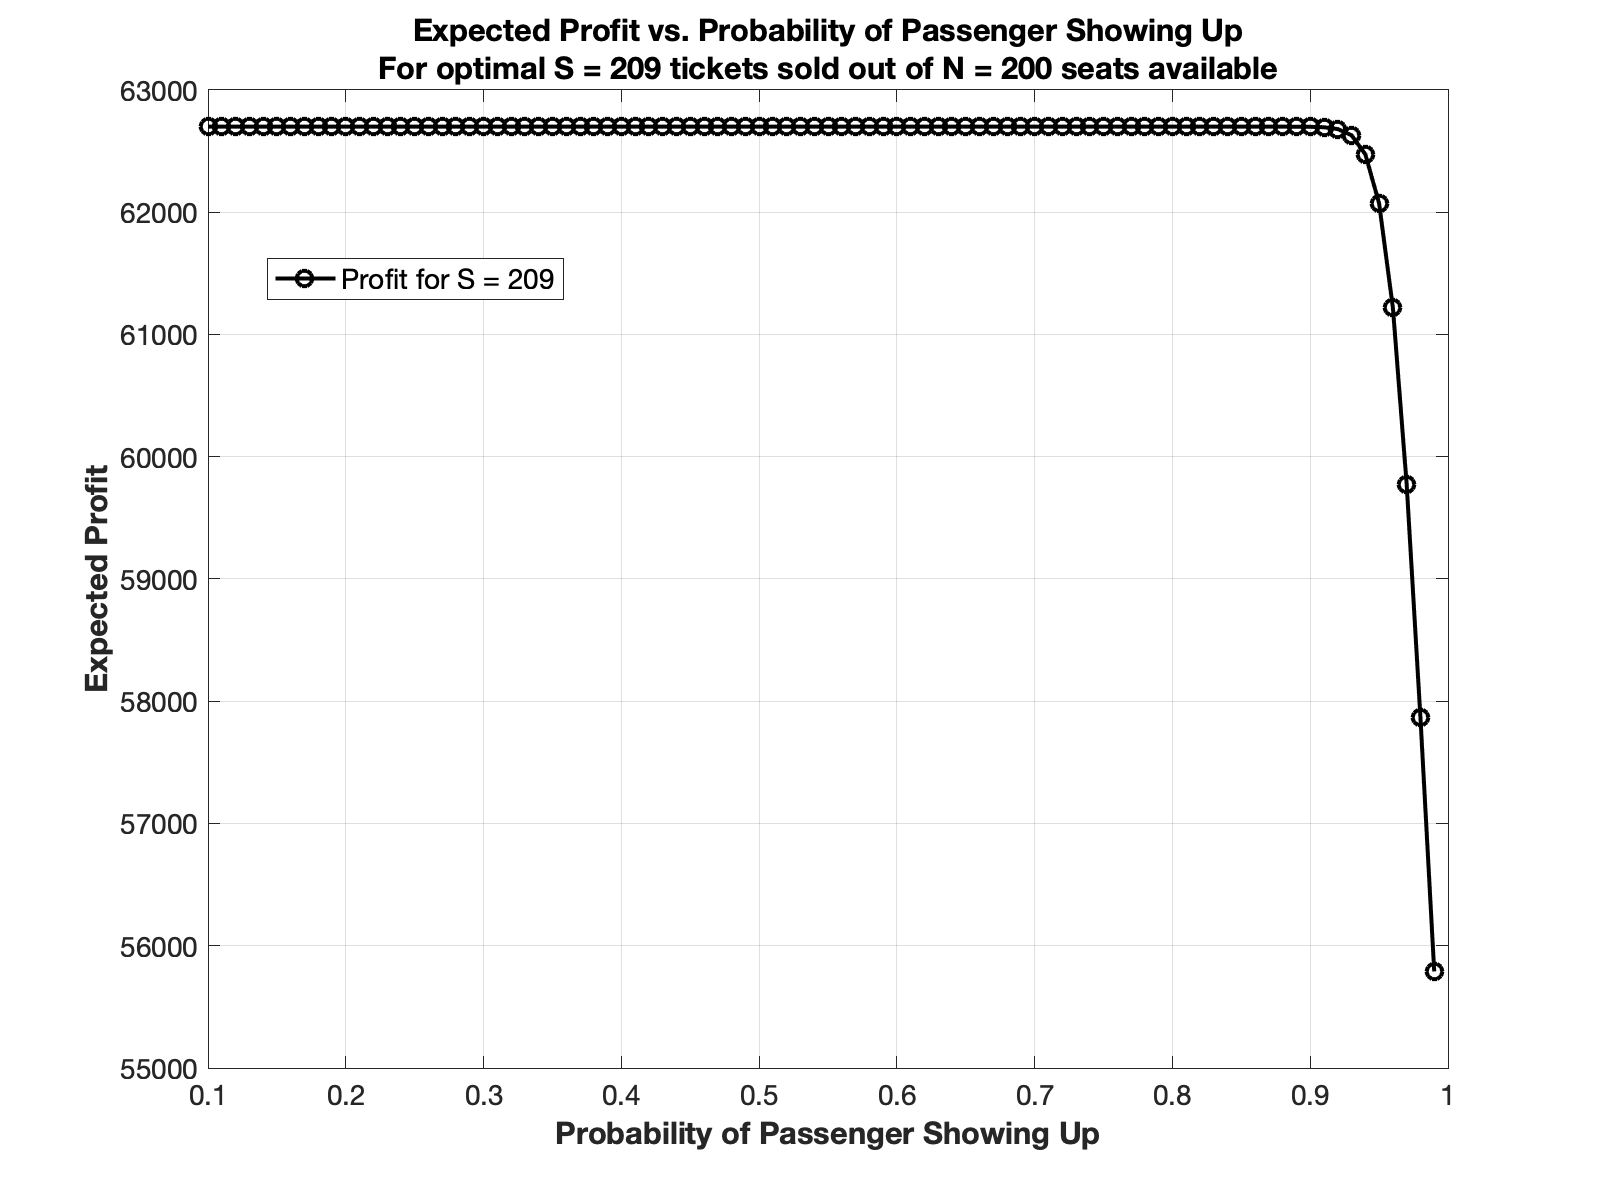

figure(Expected_Profits_Plot_p) 

### Monte Carlo Simulation: Passenger Arrival

Perform and plot a Monte Carlo simulation for passenger arrival.

Monte_Carlo_passenger_Plot = run_with_ConsoleLog(@plotPassengerArrivalSimulation, S_optimal, p, 10000); 

** Function Run:   plotPassengerArrivalSimulation 
Average number of passengers arriving: 198.57
Standard deviation of arrivals: 3.19
** Execution Time: 1.1343 seconds 
** Success:        Function plotPassengerArrivalSimulation executed with 3 inputs. 


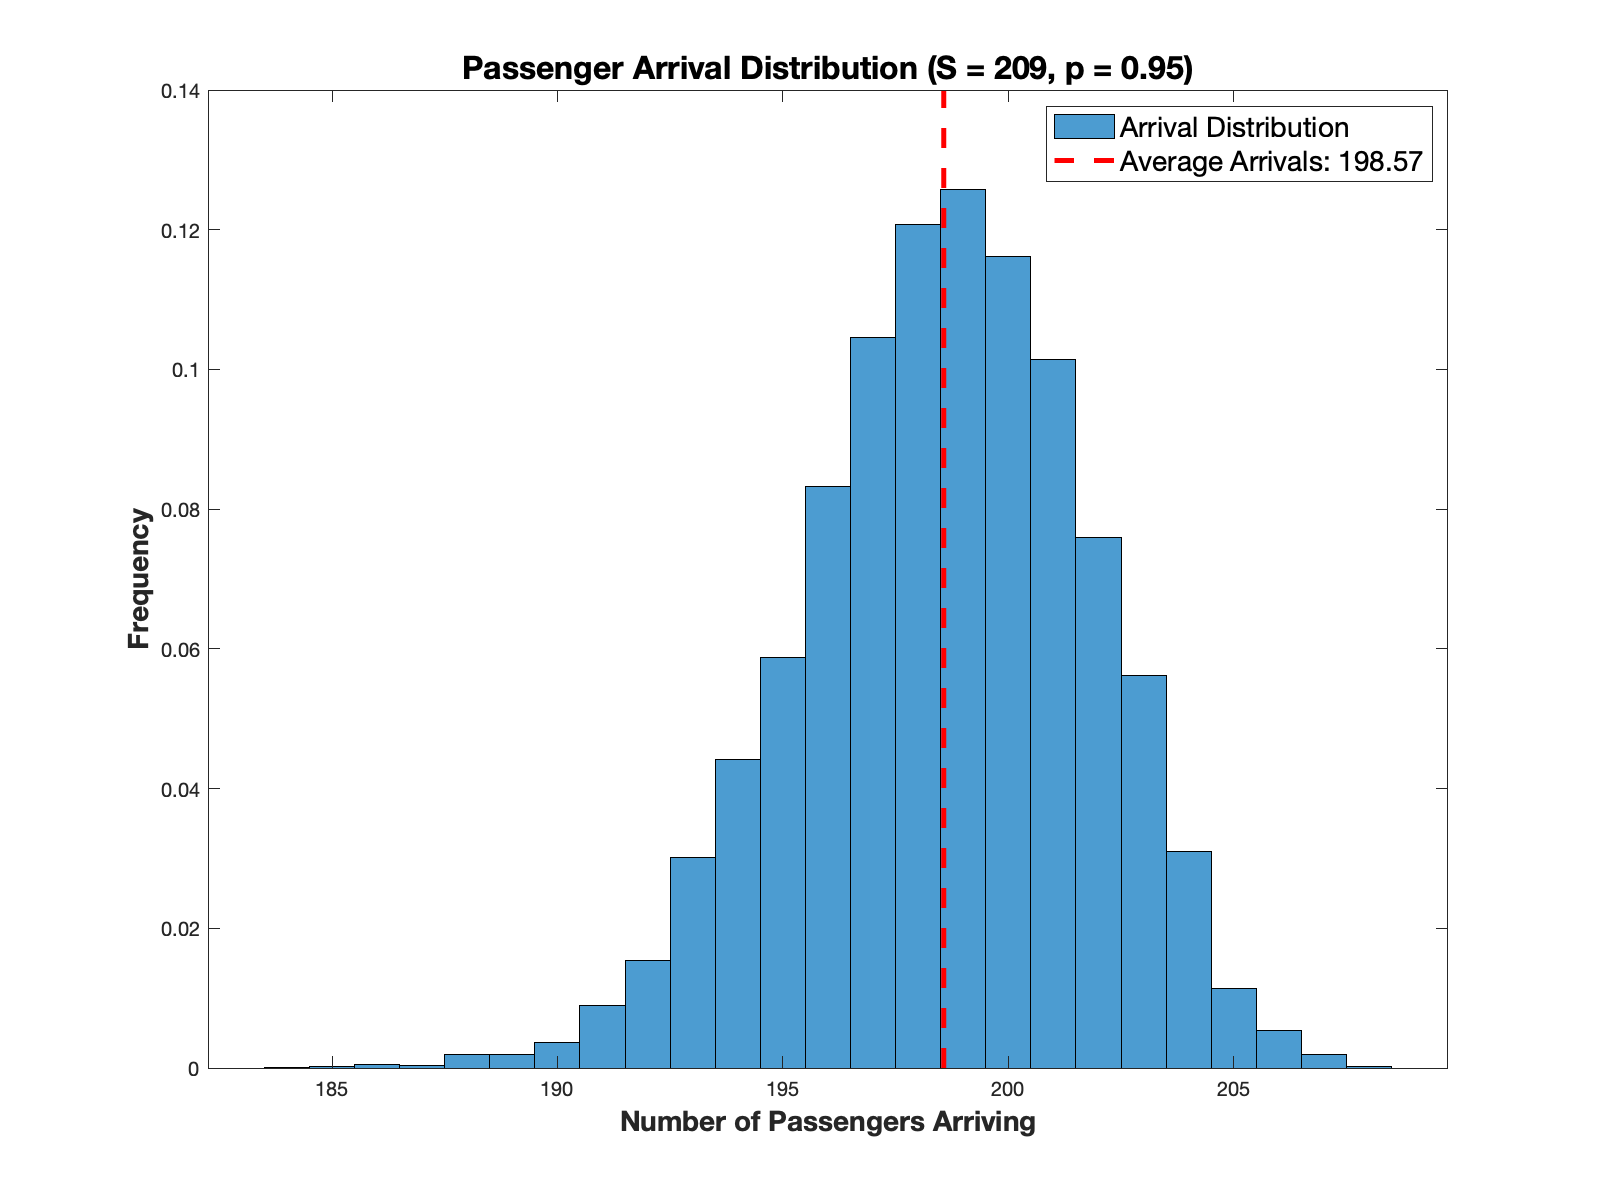

figure(Monte_Carlo_passenger_Plot) 

### Monte Carlo Simulation: Expected Profit for varying number of tickets S sold 

Perform and plot Monte Carlo simulations for expected profit with varying number of tickets sold.

Monte_Carlo_Expected_Profit_Plot_Optimal_Tickets = run_with_ConsoleLog(@plotExpectedProfitSimulation, N, S_optimal, T, p, R_0, Delta_R, P_R, lambda, shift, 500); 

** Function Run:   plotExpectedProfitSimulation 
** Execution Time: 0.3275 seconds 
** Success:        Function plotExpectedProfitSimulation executed with 10 inputs. 


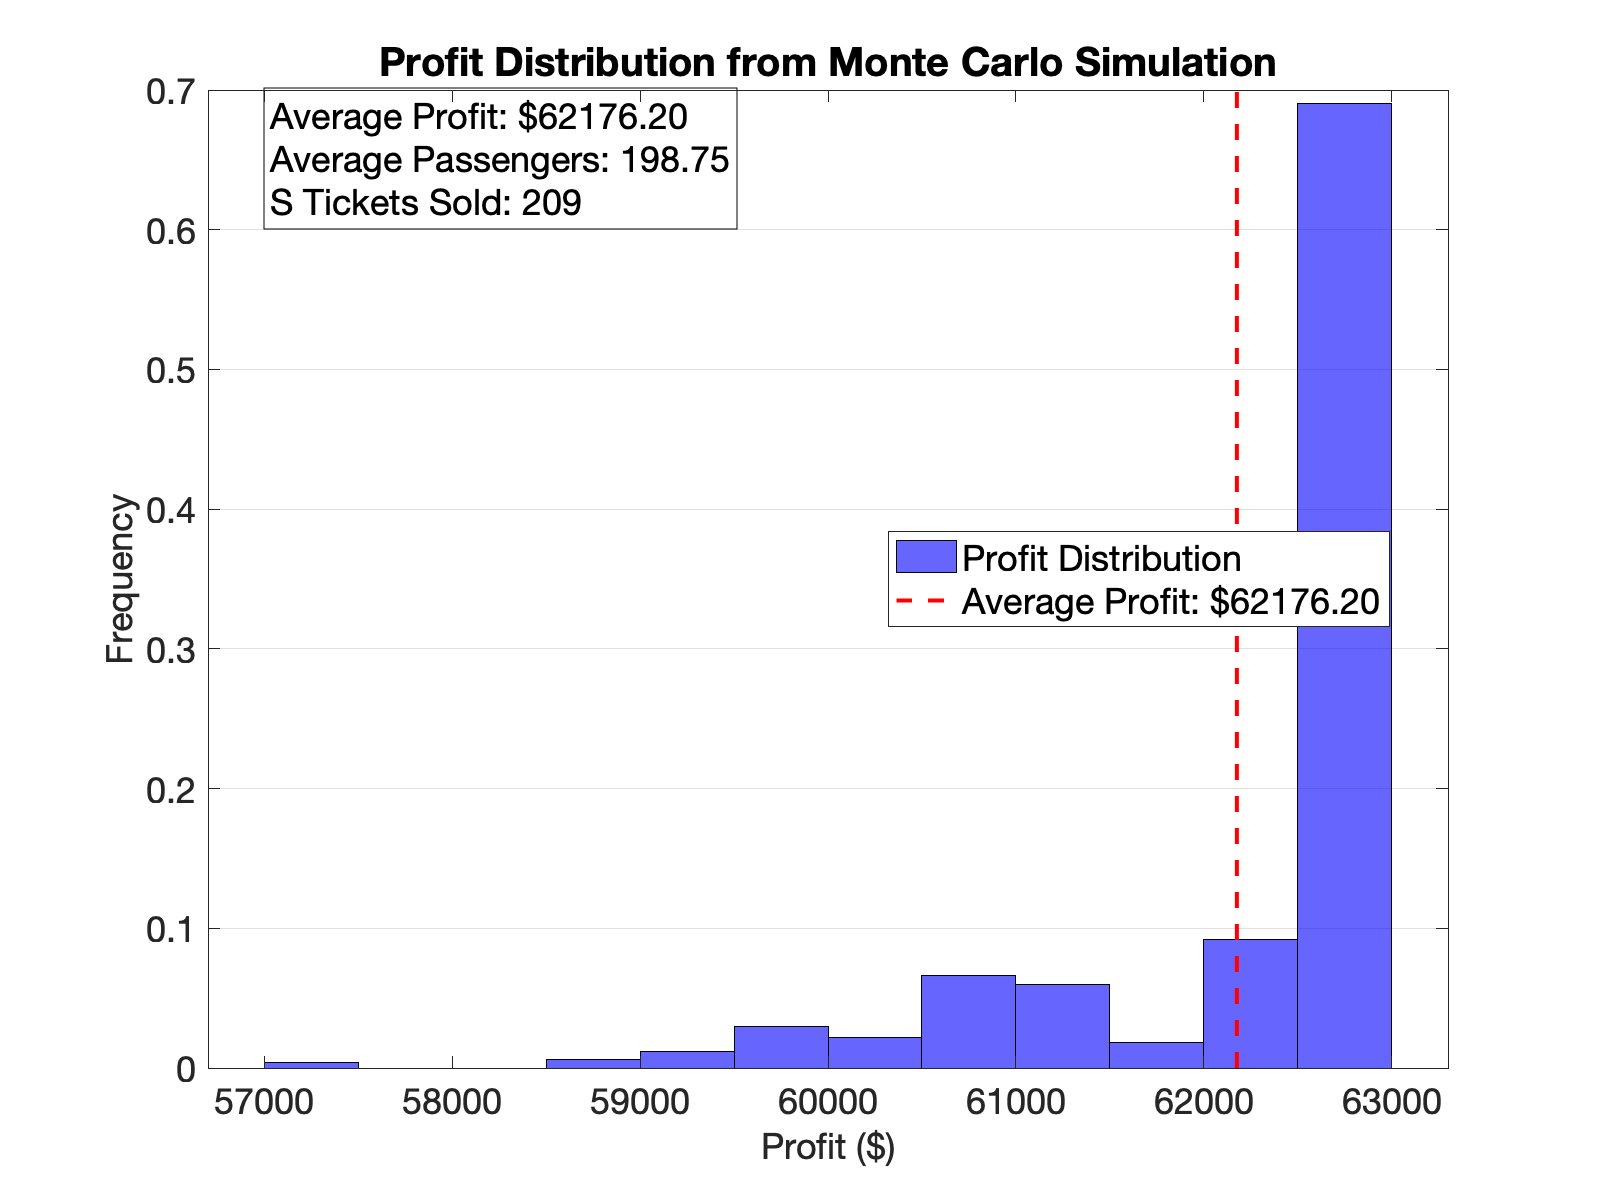

figure(Monte_Carlo_Expected_Profit_Plot_Optimal_Tickets);

Additional simulations for specific numbers of tickets sold.

Monte_Carlo_Expected_Profit_Plot_210_Tickets = run_with_ConsoleLog(@plotExpectedProfitSimulation, N, 210, T, p, R_0, Delta_R, P_R, lambda, shift, 500);

** Function Run:   plotExpectedProfitSimulation 
** Execution Time: 0.2220 seconds 
** Success:        Function plotExpectedProfitSimulation executed with 10 inputs. 


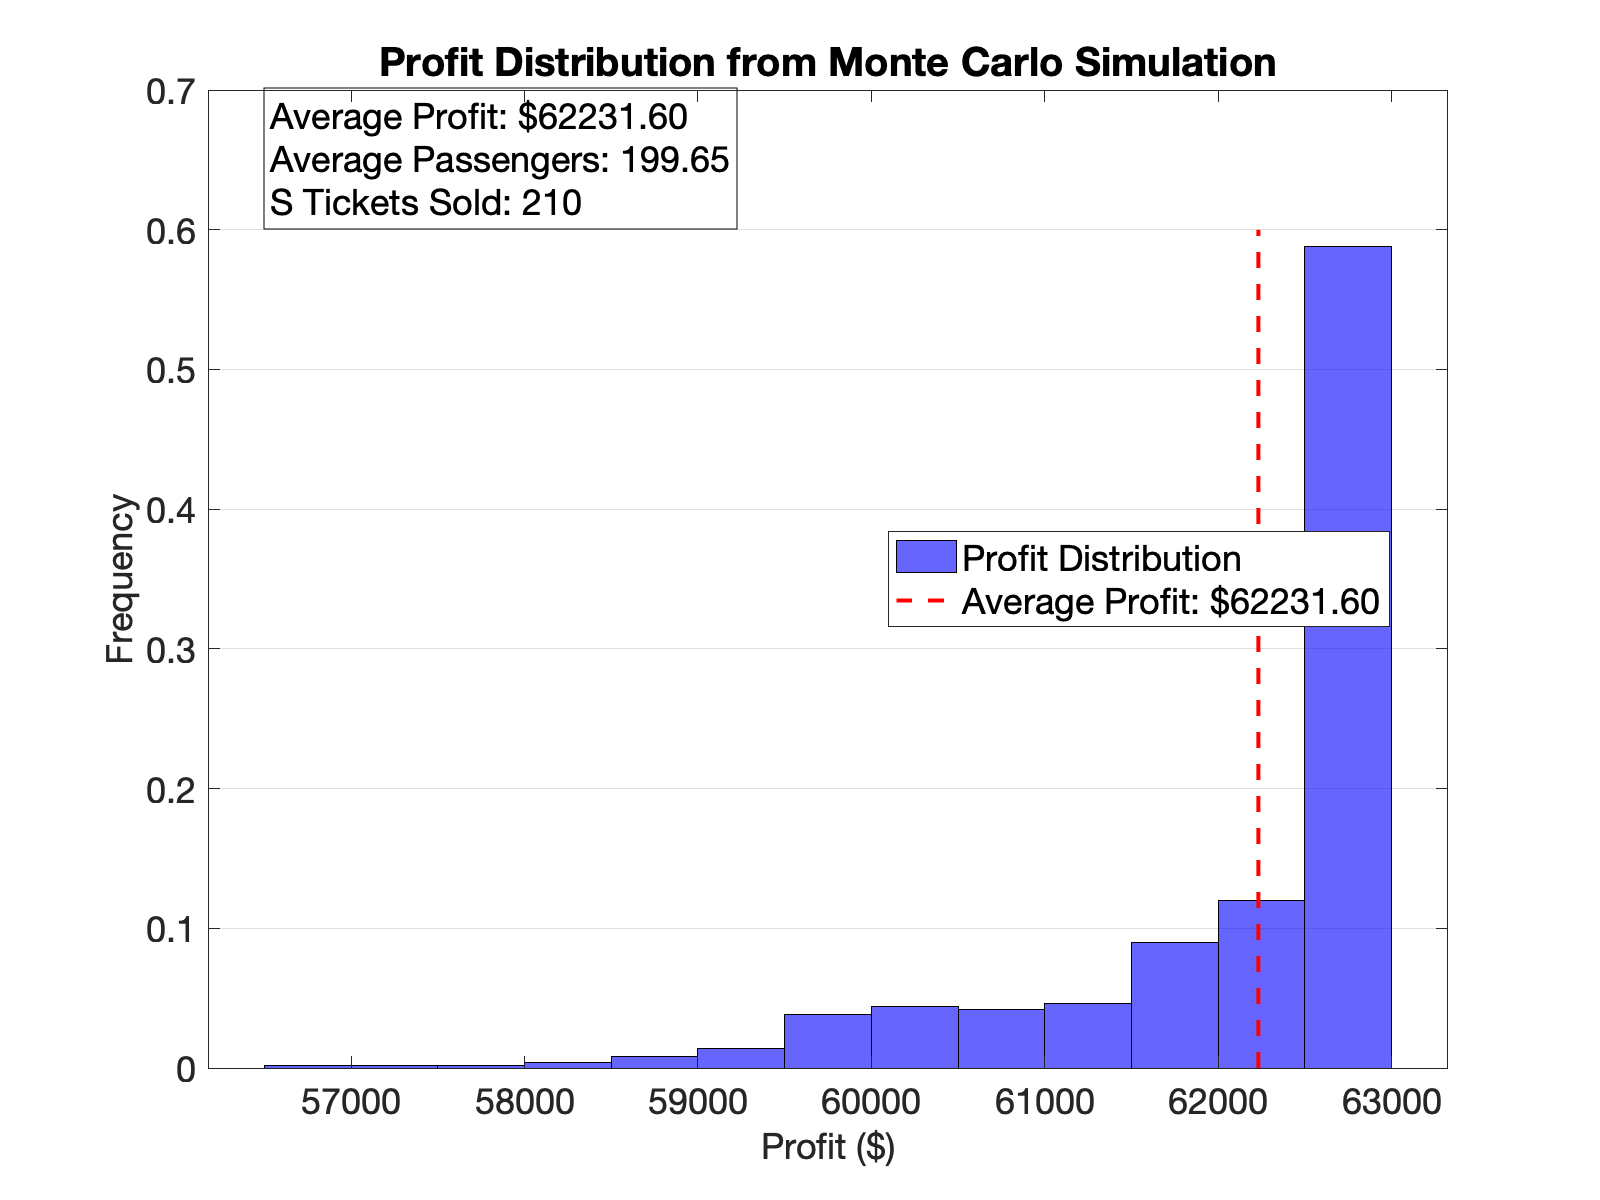

figure(Monte_Carlo_Expected_Profit_Plot_210_Tickets);

Monte_Carlo_Expected_Profit_Plot_215_Tickets = run_with_ConsoleLog(@plotExpectedProfitSimulation, N, 215, T, p, R_0, Delta_R, P_R, lambda, shift, 500);

** Function Run:   plotExpectedProfitSimulation 
** Execution Time: 0.1735 seconds 
** Success:        Function plotExpectedProfitSimulation executed with 10 inputs. 


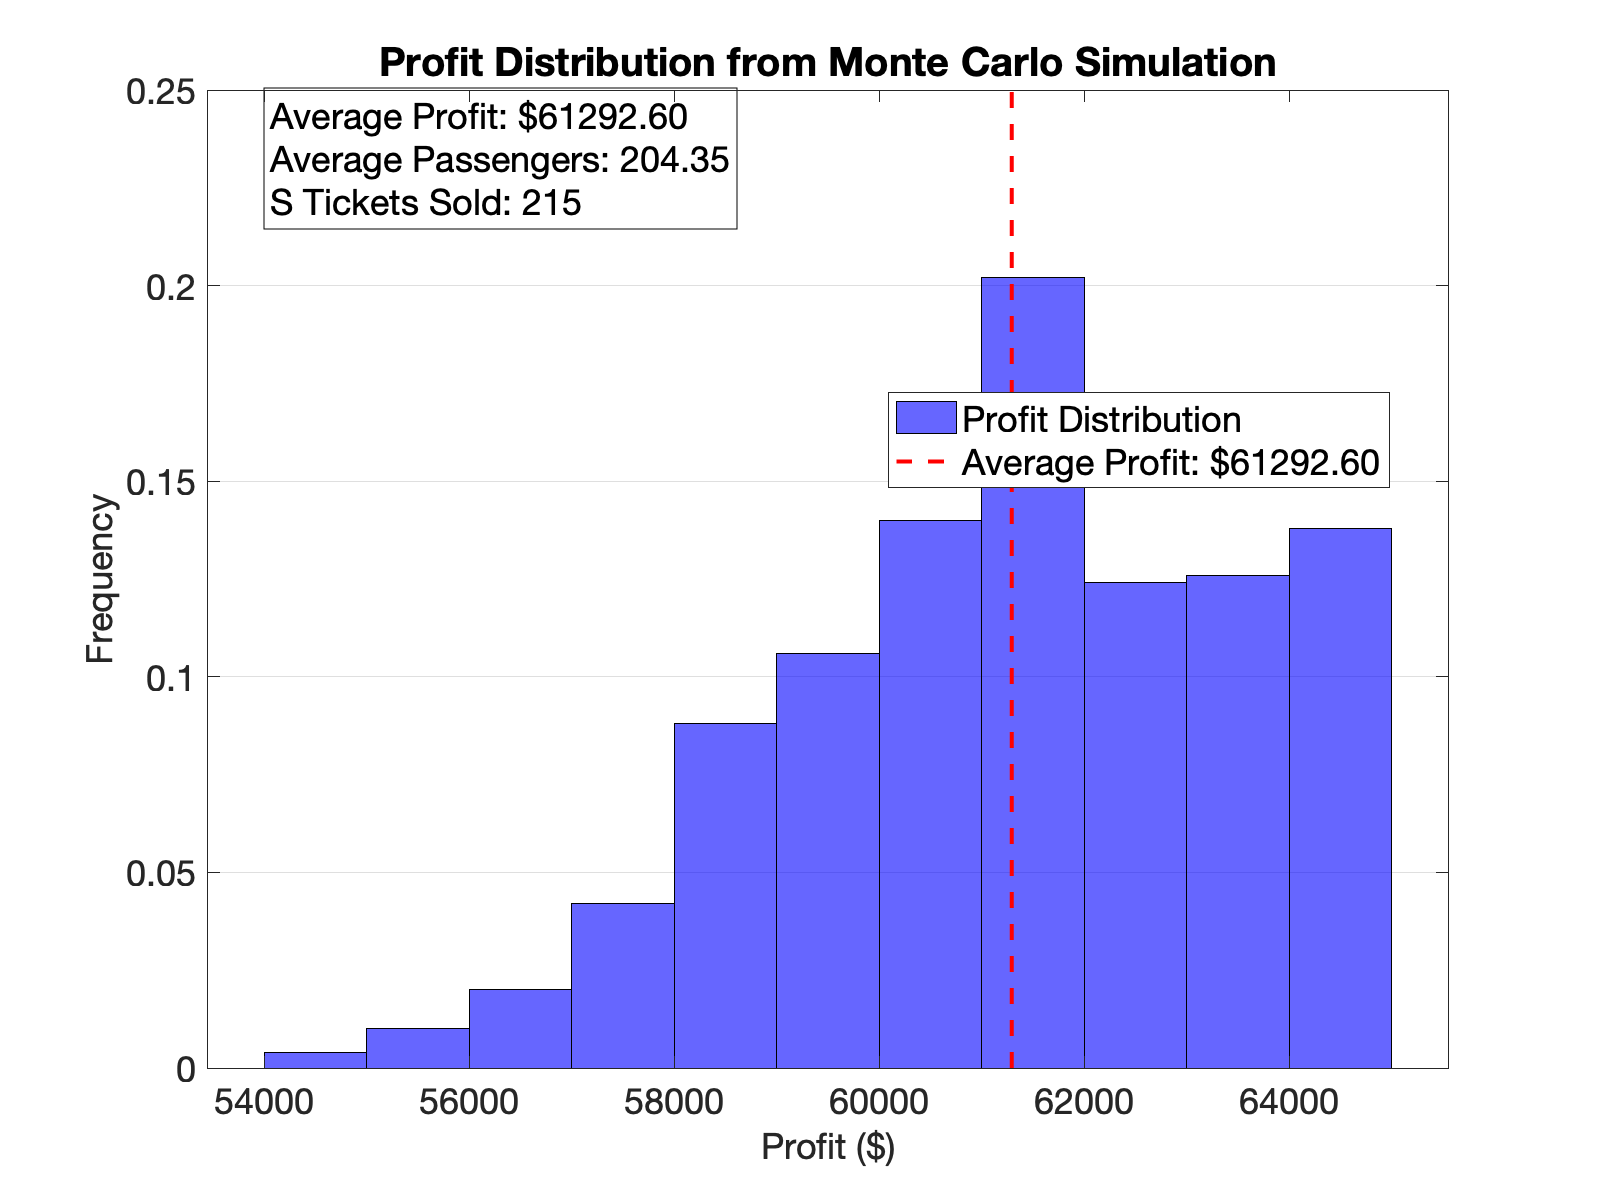

figure(Monte_Carlo_Expected_Profit_Plot_215_Tickets);

Monte_Carlo_Expected_Profit_Plot_220_Tickets = run_with_ConsoleLog(@plotExpectedProfitSimulation, N, 220, T, p, R_0, Delta_R, P_R, lambda, shift, 500); 

** Function Run:   plotExpectedProfitSimulation 
** Execution Time: 0.3359 seconds 
** Success:        Function plotExpectedProfitSimulation executed with 10 inputs. 


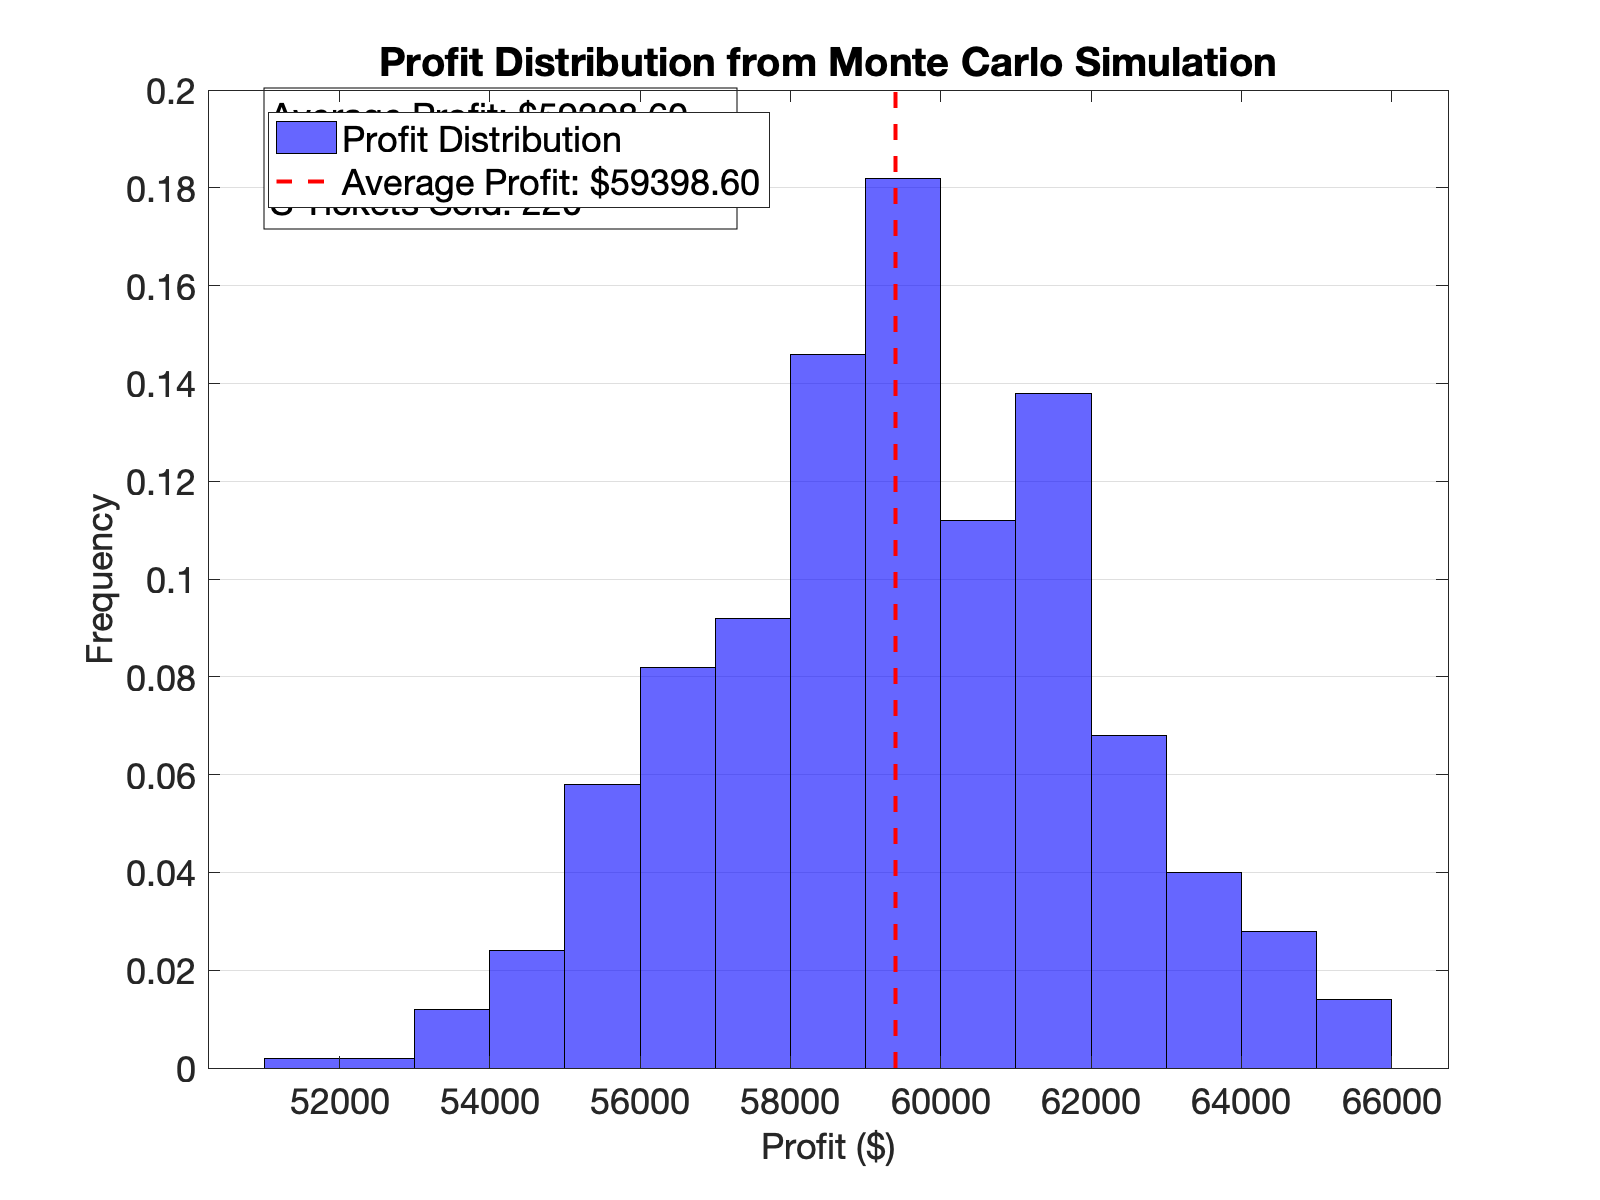

figure(Monte_Carlo_Expected_Profit_Plot_220_Tickets);

Monte_Carlo_Expected_Profit_Plot_240_Tickets = run_with_ConsoleLog(@plotExpectedProfitSimulation, N, 240, T, p, R_0, Delta_R, P_R, lambda, shift, 500);

** Function Run:   plotExpectedProfitSimulation 
** Execution Time: 0.1789 seconds 
** Success:        Function plotExpectedProfitSimulation executed with 10 inputs. 


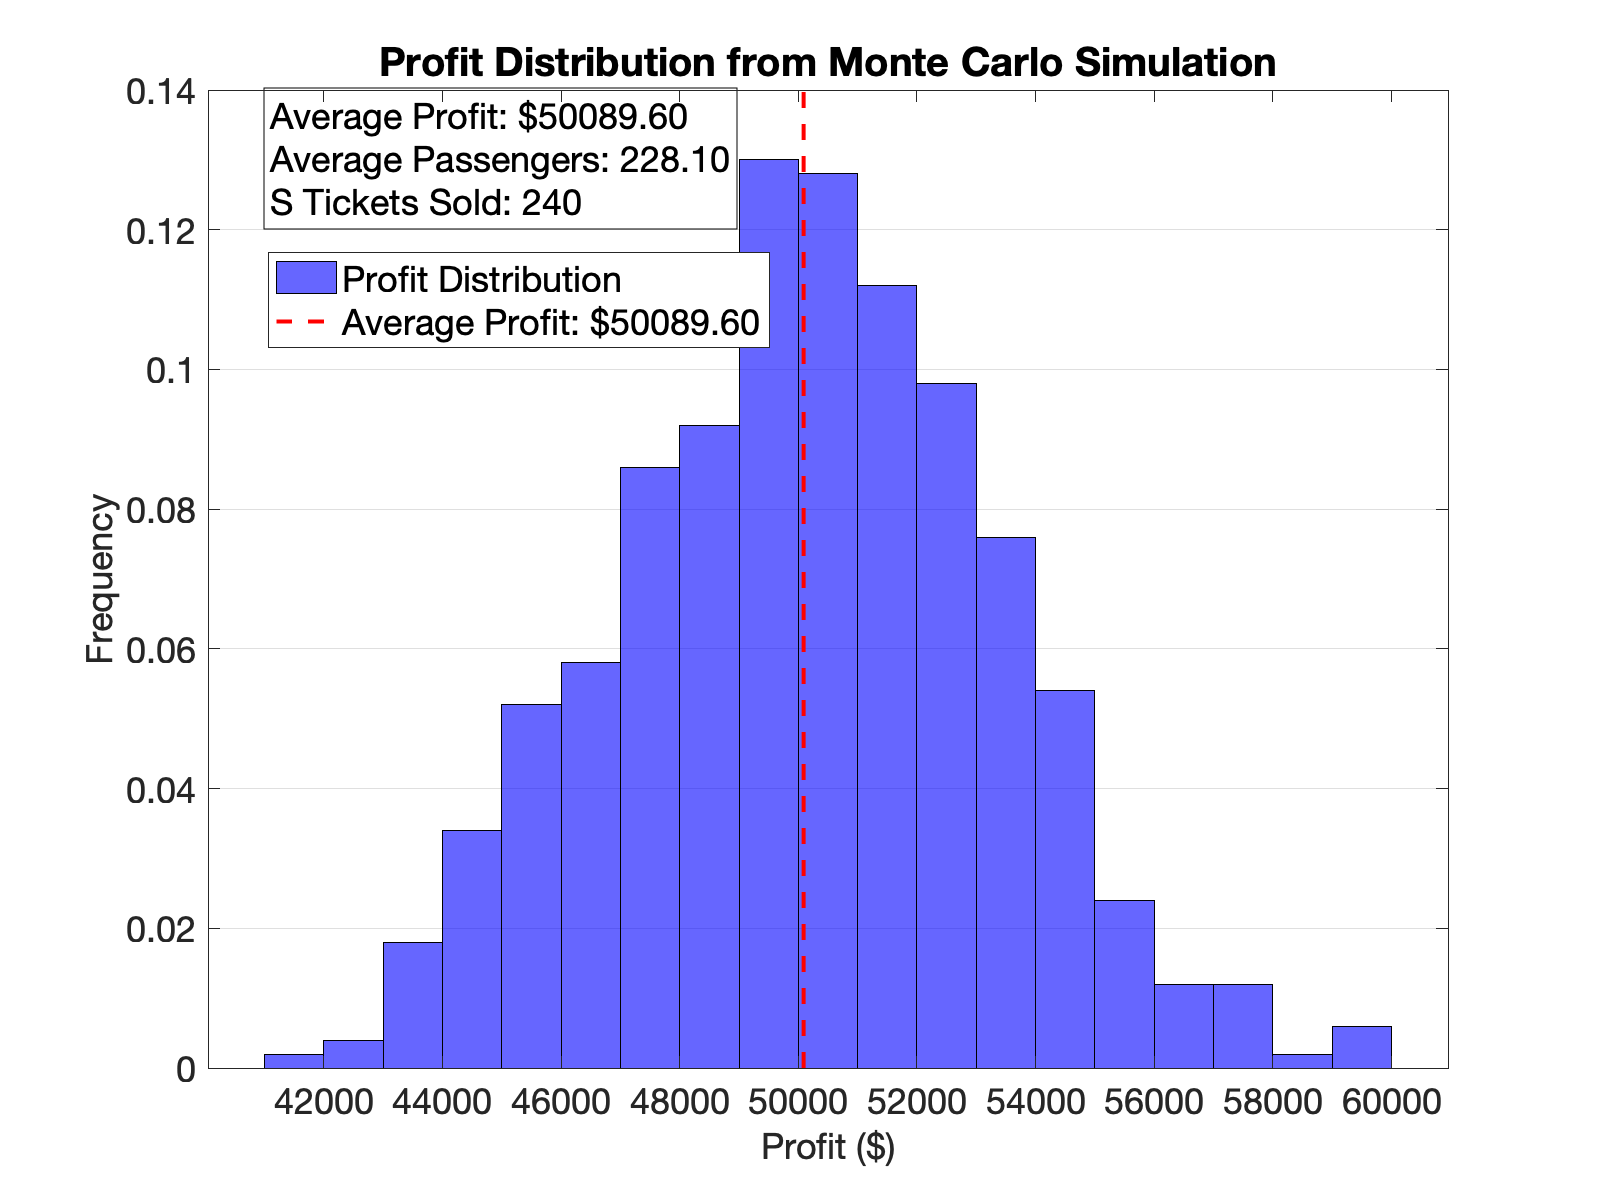

figure(Monte_Carlo_Expected_Profit_Plot_240_Tickets);